# Examine Well-Trained OutSeq trials using FISC naive bayesian - Ordinal Coding w/True Withdrawal Alignment

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

numChancePerms = 10;

postCLim = [0 0.05];
cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

%#ok<*UNRCH>


## Compile Data

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1
        % Posteriors
        posMargProbOSC = cell(1,length(fileDirs));
        odrMargProbOSC = cell(1,length(fileDirs));
        posChanceOSC = cell(1,length(fileDirs));
        odrChanceOSC = cell(1,length(fileDirs));
    end
    mlb.binSize = 200;
    mlb.dsRate = 50;
    mlb.windows = {[-500 500]};
    mlb.alignments = {'PokeIn'};
    mlb.bayesType = 1;
    mlb.SetLikes_FISC;
    % Step through OutSeq trials and align the likelihoods to the port withdrawal time of the OutSeq trial
    oscNdxs = find(([mlb.trialInfo.Position] - [mlb.trialInfo.Odor] ~= 0) & [mlb.trialInfo.Performance]==1); % All OutSeq
%     oscNdxs = find(([mlb.trialInfo.Position] - [mlb.trialInfo.Odor] ~= 0) & [mlb.trialInfo.Performance]==1 & [mlb.trialInfo.Odor]==1); % Comment IN to EXCLUDE ODOR A
    oscPosProb = nan(length(mlb.obsvTimeVect), length(oscNdxs));
    oscOdrProb = nan(length(mlb.obsvTimeVect), length(oscNdxs));
    oscPosChanceProb = nan(length(mlb.obsvTimeVect), length(oscNdxs));
    oscOdrChanceProb = nan(length(mlb.obsvTimeVect), length(oscNdxs));
    for osc = 1:length(oscNdxs)
        mlb.alignmentOffset = mlb.trialInfo(oscNdxs(osc)).PokeOutIndex - mlb.trialInfo(oscNdxs(osc)).PokeInIndex;
        mlb.SetLikes_FISC;
        mlb.obsvTrlSpikes(:,:,mlb.postTrlIDs~=oscNdxs(osc)) = [];
        mlb.Process_Observes;
        tempPosMargs = mlb.TabulateBayesPost(mlb.post, mlb.decodeIDvects(:,3));
        oscPosProb(:,osc) = tempPosMargs(:,mlb.trialInfo(oscNdxs(osc)).Position);
        oscOdrProb(:,osc) = tempPosMargs(:,mlb.trialInfo(oscNdxs(osc)).Odor);
        
        tempPosChance = nan(length(mlb.obsvTimeVect), numChancePerms);
        tempOdrChance = nan(length(mlb.obsvTimeVect), numChancePerms);
        tempLikes = mlb.likeTrlSpikes;
        for perm = 1:numChancePerms
            chancePerm_P = permute(reshape(randperm(numel(mlb.fiscTrials)), size(mlb.fiscTrials)), [1,3,2]);
            tempLikesPerm = tempLikes(chancePerm_P);
            for t = 1:length(mlb.obsvTimeVect)
                chancePerm_T = randperm(size(mlb.likeTrlSpikes{t},1));
                tempLikesPerm{t} = tempLikesPerm{t}(chancePerm_T,:);
            end
            mlb.likeTrlSpikes = tempLikesPerm;
            mlb.Process_Observes;
            tempPosMargs = mlb.TabulateBayesPost(mlb.post, mlb.decodeIDvects(:,3));
            tempPosChance(:,perm) = tempPosMargs(:,mlb.trialInfo(oscNdxs(osc)).Position);
            tempOdrChance(:,perm) = tempPosMargs(:,mlb.trialInfo(oscNdxs(osc)).Odor);
        end
        oscPosChanceProb(:,osc) = mean(tempPosChance,2);
        oscOdrChanceProb(:,osc) = mean(tempOdrChance,2);
    end
    posMargProbOSC{ani} = oscPosProb;
    odrMargProbOSC{ani} = oscOdrProb;
    posChanceOSC{ani} = oscPosChanceProb;
    odrChanceOSC{ani} = oscOdrChanceProb;
end

Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed


posMargProbOSC = cell2mat(posMargProbOSC);
odrMargProbOSC = cell2mat(odrMargProbOSC);
posChanceOSC = mean(cell2mat(posChanceOSC),2);
odrChanceOSC = mean(cell2mat(odrChanceOSC),2);
toc

Elapsed time is 246.714089 seconds.


## Plot Position vs Odor Coding for OutSeq Trials

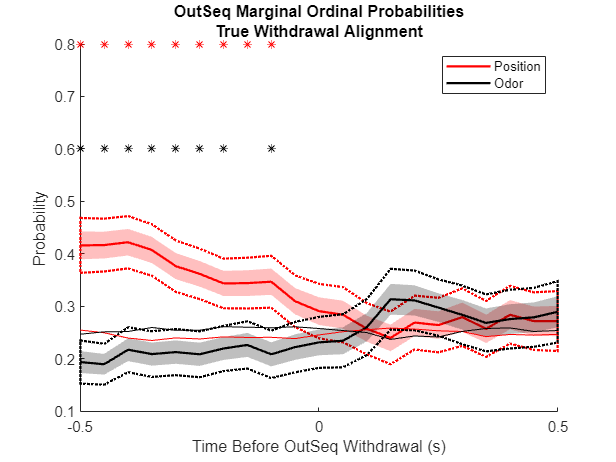

figure;
plt = nan(1,2);
plt(1) = mlb.PlotMeanVarLine((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, posMargProbOSC,2,0.05,'r');
plt(2) = mlb.PlotMeanVarLine((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, odrMargProbOSC,2,0.05,'k');
plot((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, posChanceOSC, 'r');
plot((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, odrChanceOSC, 'k');

posSigLog = false(1,length(mlb.obsvTimeVect));
odrSigLog = false(1,length(mlb.obsvTimeVect));
opDiffSigLog = false(1,length(mlb.obsvTimeVect));
for t = 1:length(mlb.obsvTimeVect)
    posSigLog(t) = ttest(posMargProbOSC(t,:), posChanceOSC(t), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
    odrSigLog(t) = ttest(odrMargProbOSC(t,:), odrChanceOSC(t), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
    opDiffSigLog(t) = ttest(posMargProbOSC(t,:), odrMargProbOSC(t,:), 'Alpha', 0.05/length(mlb.obsvTimeVect));
end
posSigLog = posSigLog*.8;
posSigLog(posSigLog==0) = nan;
scatter((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, posSigLog, '*r');

odrSigLog = odrSigLog*.7;
odrSigLog(odrSigLog==0) = nan;
scatter((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, odrSigLog, '*k');

opDiffSigLog = opDiffSigLog*.6;
opDiffSigLog(opDiffSigLog==0) = nan;
scatter((mlb.windows{1}(1):mlb.dsRate:mlb.windows{1}(2))/1000, opDiffSigLog, '*k');

xlabel('Time Before OutSeq Withdrawal (s)');
ylabel('Probability');
title([{'OutSeq Marginal Ordinal Probabilities'};{'True Withdrawal Alignment'}]);
legend(gca, plt, [{'Position'}, {'Odor'}]);